# Homework #3

## Problem 1 (50 points) 

An enginer wants to laser cut a shape out of a piece of wood.  The shape happens to be that of a goose as defined and illustrated by the code below. In this code, we plot a smooth curve x(t), y(t) parametrically, where the parameter t ranges from 0 to 300.  This paramter could have different meanings, but in this case we will think of it as time, with the cutting starting at t = 0sec and having a total duration of 300 seconds.  In order to get consistent results, the laser should move at constant speed.  Otherwise, in areas where the laser moves quickly, the sheet will not be cut through and in areas where the laser moves slowly, the sheet will be burned excessively.  The parameterization defined below does not accomplish this objective by itself.  It moves too quickly in some areas and too slowly in other areas.  Your goal is to use calculus and numerical methods to re-parameterize the curve so that the laser will move at constant speed.

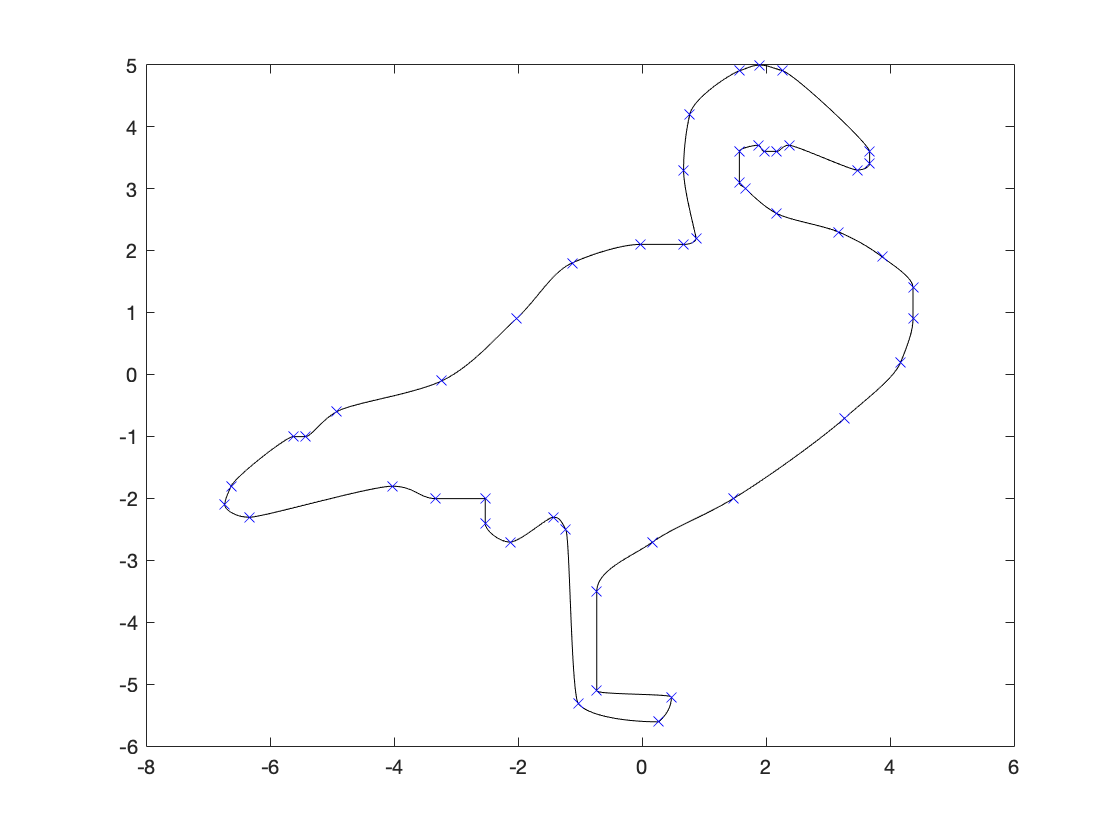

clear all; close all, clc
goose=load_goose();
i=1:length(goose);
x=@(p) interp1((300/48)*(i-1),goose(:,1),p,'pchip');
y=@(p) interp1((300/48)*(i-1),goose(:,2),p,'pchip');
p=(300/48)*(0:0.01:i(end)-1);
plot(x(p),y(p),'k')
axis equal
xlim([-8 6])
ylim([-6 5])
hold on 
plot(goose(:,1),goose(:,2),'bx')

Here is some background that will help you for this problem.  We can think of the laser position as following a vector valued function $\mathbf{f}\left(t\right)=\left\lbrack x\left(t\right);y\left(t\right)\right\rbrack$ in the sense that the mechanical system (let's say stepper motors and belts) reliably brings the laser to a location $\left\lbrack x\left(t\right);y\left(t\right)\right\rbrack$at every instant in time $t$.  The length of the cut created during the time interval $0$ to $t_b$ is the definite integral of the 2-norm of the derivative $\left|\left.\mathbf{f}\prime \left(t\right)\right)\right|$


$$\int_0^{t_b } \left|\left.\mathbf{f}\prime \left(t\right)\right)\right|\textrm{dt}=\int_0^{t_b } \sqrt{{\left(\frac{d}{\mathrm{d}t}x\left(t\right)\right)}^2 +{\left(\frac{d}{\mathrm{d}t}y\left(t\right)\right)}^2 }\textrm{dt}$$


To understand the term "length of the cut", imagine a piece of string that lays on top of the cut and follows all its curves.  If that string were pulled straight and measured with a meter stick, that would comprise a measurement of the  "length of the cut". 

a) (15 points) Use trapezoid rule with 100 equally spaced segments in time to compute the length of the cut made from $t$= 0 sec to 1 sec.  Use a forward difference with $\Delta t=$ 0.01 sec to numerically estimate the derivatives.  Store your result in a variable named cut_length_1sec.

% Your calculations here
tvals = linspace(0,1,101); %100 intervals so dt = 0.01
xvals = x(tvals);
yvals = y(tvals);
dx_dt = ones(1,100);
dy_dt = ones(1,100);
dt = tvals(2)-tvals(1);
for i = 1:length(tvals)-1
    dx = xvals(i+1)-xvals(i);
    dy = yvals(i+1)-yvals(i);
    dx_dt(i) = dx./dt;
    dy_dt(i) = dy./dt;
end
integrand = sqrt((dx_dt.^2) + (dy_dt.^2));
cut_length_1sec = trapz(tvals(1:100), integrand)

cut_length_1sec = 0.2879

b) (10 points) Extend the results from part (a) to compute total accumulated length of the cut produced so far at 300 different instants in time -- specifically $t$= 1 sec, $t$= 2 sec, up to $t$= 300 sec.  Store the results in a 1x300 vector named cut_lengths.

HINT: You already have the answer for $t$= 1 sec due to your work in part (a).  Store that in cut_lengths(1).  Add to that value the additional length of cut made from  $t$= 1 sec to 2 sec.  Store that in cut_lengths(2), and so on.  

% Your calculations here
tvals = linspace(0,300,301);
xvals = x(tvals);
yvals = y(tvals);
dt = tvals(2)-tvals(1);
integrand = ones(1,300);
cut_lengths = ones(1,300);
cut_lengths(1) = cut_length_1sec;
for i = 1:length(tvals)-1
    dx = xvals(i+1)-xvals(i);
    dy = yvals(i+1)-yvals(i);
    dx_dt = dx./dt;
    dy_dt = dy./dt;
    integrand(i) = sqrt((dx_dt.^2) + (dy_dt.^2));
end
for i = 2:length(integrand)
    cut_lengths(i) = cut_lengths(i-1)+trapz([tvals(i-1) tvals(i)], [integrand(i-1) integrand(i)]);
end
cut_lengths

cut_lengths =     0.2879    0.5704    0.8323    1.0648    1.2603    1.4134    1.5720    1.8841    2.3987    3.0091    3.6007    4.0586    4.2930    4.3756    4.4304    4.4776    4.5193    4.5593    4.6036    4.6735    4.7879    4.9375    5.0999    5.2524    5.3746    5.4689    5.5589    5.6543    5.7490    5.8362    5.9099    5.9737    6.0439    6.1257    6.2086    6.2814    6.3327    6.3573    6.3996    6.4995    6.6421    6.8065    6.9716    7.1168    7.2354    7.3395    7.4423    7.5508    7.6709    7.8116


c) (5 points) Make a plot of the cut lengths produced at every time versus time itself.

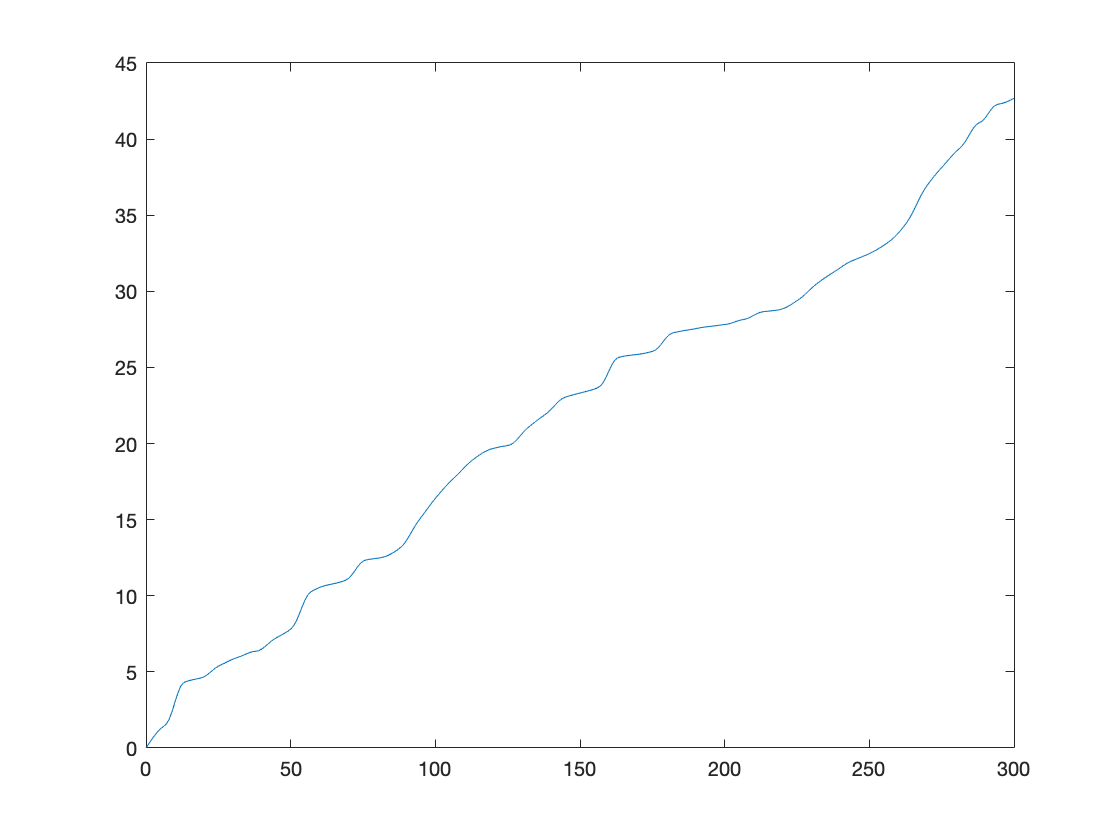

close all
% Your plotting code here
plot(tvals,[0,cut_lengths])

d) (10 points)  Use the data from your work above to create a re-parameterization of the laser's control scheme that will provide uniform cutting speed.  One effective way of doing this is to make a new function $p\left(t\right)$ so that $\mathbf{f}\left(p\left(t\right)\right)=\left\lbrack x\left(p\left(t\right)\right);y\left(p\left(t\right)\right)\right\rbrack$is such that the parameter $p$ proceeds from 0 to 300 as $t$ procedes from 0 to 300 in a manner which guarantees that the cut made in each 1 second interval is always the same.  That is:


$$\int_0^1 \sqrt{{\left(\frac{d}{\mathrm{d}t}x\left(t\right)\right)}^2 +{\left(\frac{d}{\mathrm{d}t}y\left(t\right)\right)}^2 }\textrm{dt}=\int_1^2 \sqrt{{\left(\frac{d}{\mathrm{d}t}x\left(t\right)\right)}^2 +{\left(\frac{d}{\mathrm{d}t}y\left(t\right)\right)}^2 }\textrm{dt}=\int_2^3 \sqrt{{\left(\frac{d}{\mathrm{d}t}x\left(t\right)\right)}^2 +{\left(\frac{d}{\mathrm{d}t}y\left(t\right)\right)}^2 }\textrm{dt}=\ldotp \ldotp \ldotp =\int_{299}^{300} \sqrt{{\left(\frac{d}{\mathrm{d}t}x\left(t\right)\right)}^2 +{\left(\frac{d}{\mathrm{d}t}y\left(t\right)\right)}^2 }\textrm{dt}$$


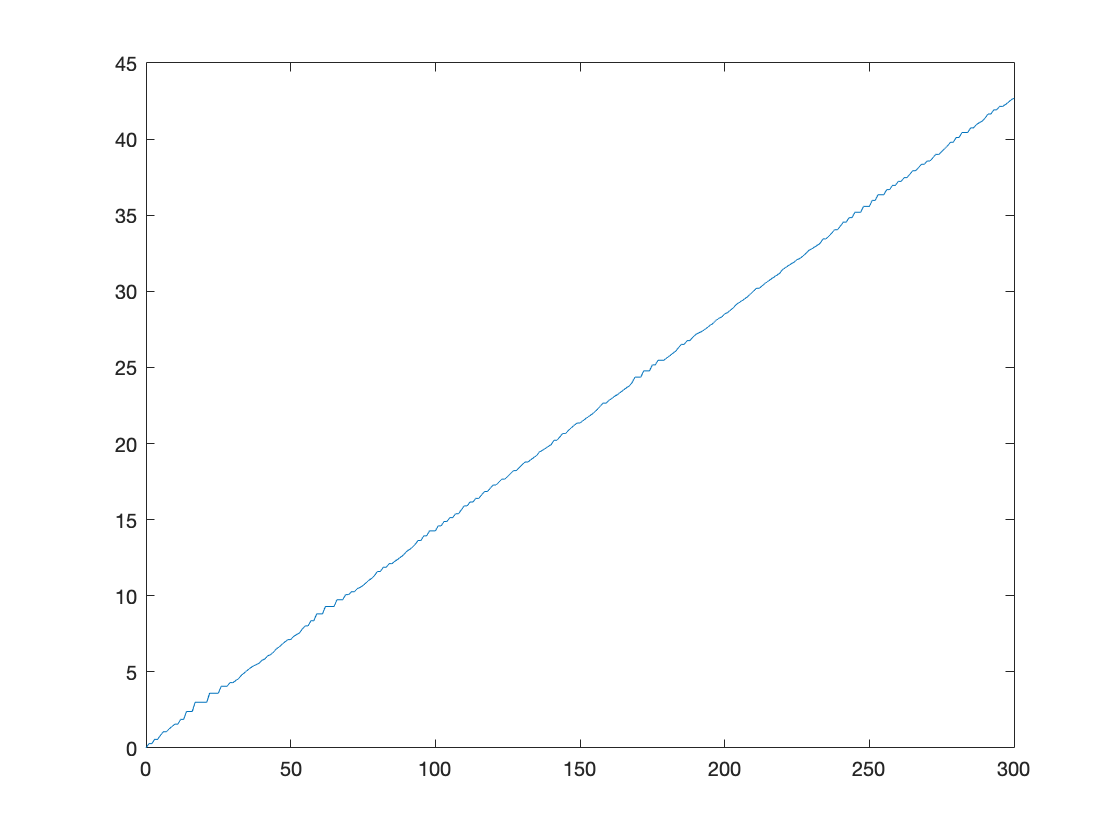

% Your code here
% (get length, find t for that length, get new t on curve for that length)
times = linspace(0,300,301);
cut_length_wzero = horzcat(0,cut_lengths);
% cuts_should_be = (times*cut_length_wzero(end))/300;
total_cut = cut_length_wzero(end);
speed = total_cut/300.00;
p = @(t) times(find(cut_length_wzero>=(t.*speed), 1,'first'));
pvals = ones(1,301);
for i = 1:length(times)
    pvals(i) = p(times(i));
end
plot(times,cut_length_wzero(pvals+1)) %should be straight line, a little wiggly bc cuts_should_be is rarely equal to any element in cut_length_wzero so pval is often a little off

e) (10 points) Make an animation of the laser cutting out the goose shape according to your arc length parameterization.

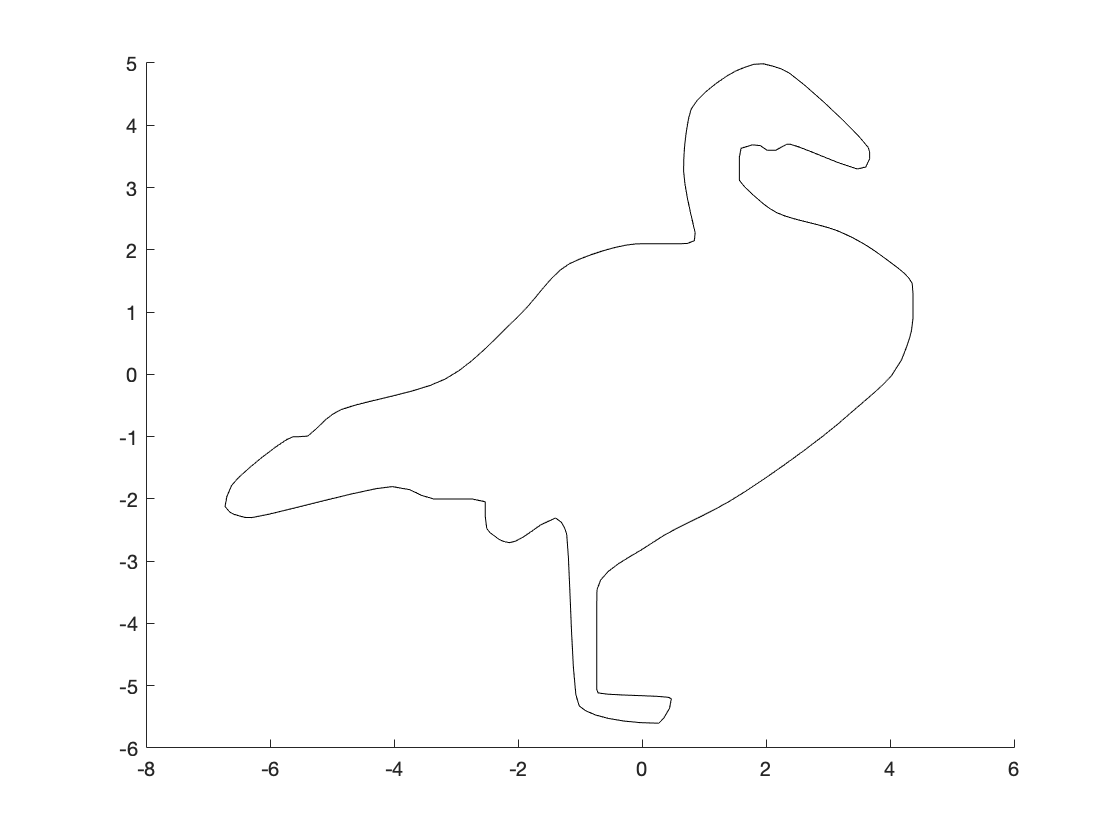

% Here are two lines that enable animation within live scripts
settingsObj = settings;
settingsObj.matlab.editor.AllowFigureAnimation.TemporaryValue = 1;
% Your code here
close all
an = animatedline;
times = linspace(0,300,301);
axis([-8 6 -6 5]);
xvals = x(pvals);
yvals = y(pvals);
for k = 1:length(xvals)
    addpoints(an,xvals(k),yvals(k));
    drawnow
end



% Note: the "drawnow" causes changes at the location of the last active
% figure (up above the code that executed the "drawnow")
% And then subsequently, the figure moves below the code.


## **Problem 2 (20 points)**

Professor Hosoi’s student, Sarah, was studying optimal weight distribution in ﬁeld hockey sticks. To test her theories, Sarah took video images of an athlete hitting a ball with a ﬁeld hockey stick and extracted the trajectory of the stick head. Her data from one trial is here:

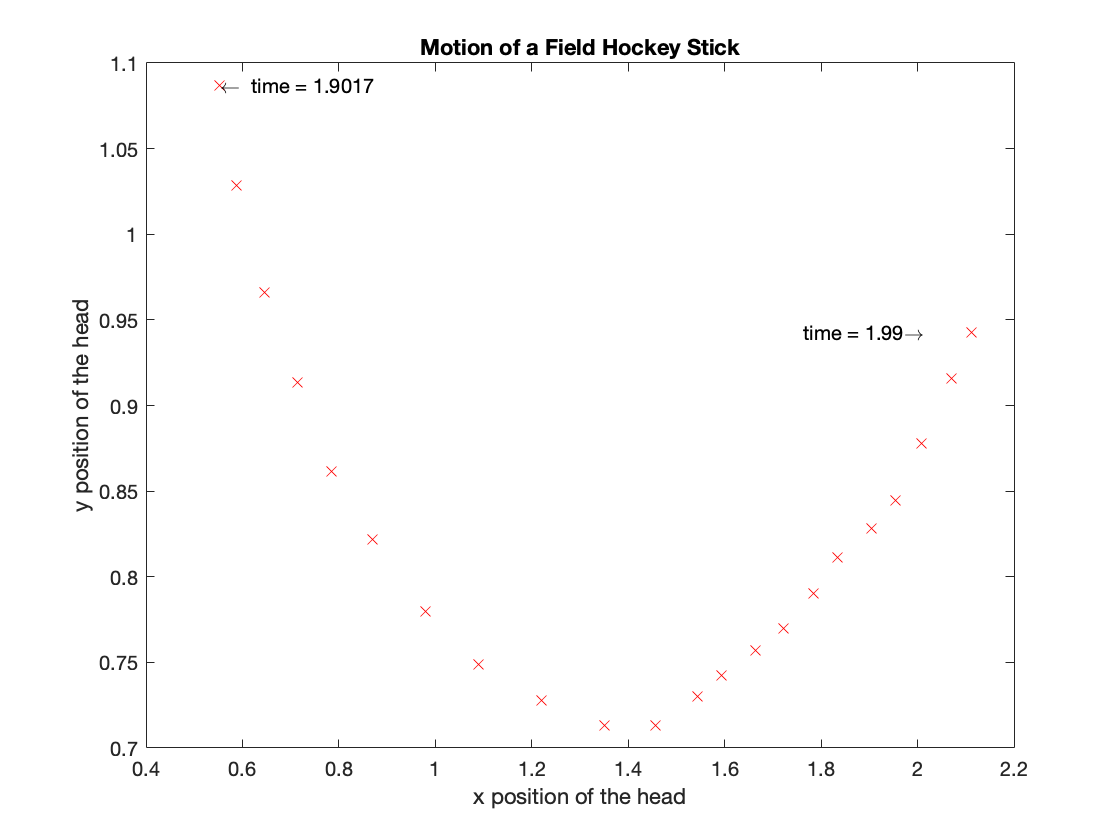

clear all
close all
t=[ 1.901666667 1.906666667 1.91 1.915 1.918333333 1.923333333 1.926666667 1.931666667 1.935 1.94 1.943333333 1.948333333 1.951666667 1.956666667 1.96 1.965 1.968333333 1.973333333 1.976666667 1.981666667 1.985 1.990];
x_stick=[ 0.55257759 0.588068821 0.646524966 0.713331989 0.784314451 0.86991095 0.980560082 1.089121494 1.220647821 1.350086428 1.456560121 1.544244339 1.594349606 1.663244349 1.721700494 1.784332078 1.834437346 1.905419808 1.953437356 2.007718062 2.070349646 2.112104035];
y_stick=[ 1.086866757 1.028410612 0.965779028 0.913586041 0.861393054 0.821726384 0.779971995 0.748656203 0.727779008 0.713164972 0.713164972 0.729866727 0.742393044 0.757007081 0.769533397 0.790410592 0.811287787 0.827989543 0.844691298 0.87809481 0.91567376 0.942814114];

plot(x_stick,y_stick,'rx')
title('Motion of a Field Hockey Stick')
xlabel('x position of the head')
ylabel('y position of the head')
text(x_stick(1),y_stick(1),['\leftarrow  time = ' num2str(t(1))])
text(x_stick(end)-0.35,y_stick(end),['time = ' num2str(t(end)) '\rightarrow'])

The data includes a vector for the x-position of the end of the stick (named `x_stick)`, a vector for the y-position of the end of the stick (named `y_stick)`, and a vector of the corresponding times (named `t)`. 

a) (3 points) Use a forward diﬀerence scheme to approximate the vertical component of velocity at the first 20 times in the vector t.  Place your results in a vector named `y_vel`.

% Your code here:
times = t(1:20);
y_vel = ones(1,20);
for i = 1:length(times)
    y_vel(i) = (y_stick(i+1)-y_stick(i))/(t(i+1)-t(i));
end
y_vel

y_vel =   -11.6912  -18.7895  -10.4386  -15.6579   -7.9333  -12.5263   -6.2632   -6.2632   -2.9228         0    3.3404    3.7579    2.9228    3.7579    4.1754    6.2632    3.3404    5.0105    6.6807   11.2737


b) (2 points) Use a forward diﬀerence scheme to approximate the horizontal component of velocity at the first 20 times in the vector t.   Place your results in a vector named `x_vel`.

% Your code here:
times = t(1:20);
x_vel = ones(1,20);
for i = 1:length(times)
    x_vel(i) = (x_stick(i+1)-x_stick(i))/(t(i+1)-t(i));
end
x_vel

x_vel =     7.0982   17.5368   13.3614   21.2947   17.1193   33.1947   21.7123   39.4579   25.8877   31.9421   17.5368   15.0316   13.7789   17.5368   12.5263   15.0316   14.1965   14.4053   10.8561   18.7895


c) (1 points) Plot the result from part b so that you can visualize the effects of noise on the estimates.  This can be done by making a plot of `x_vel versus t.`

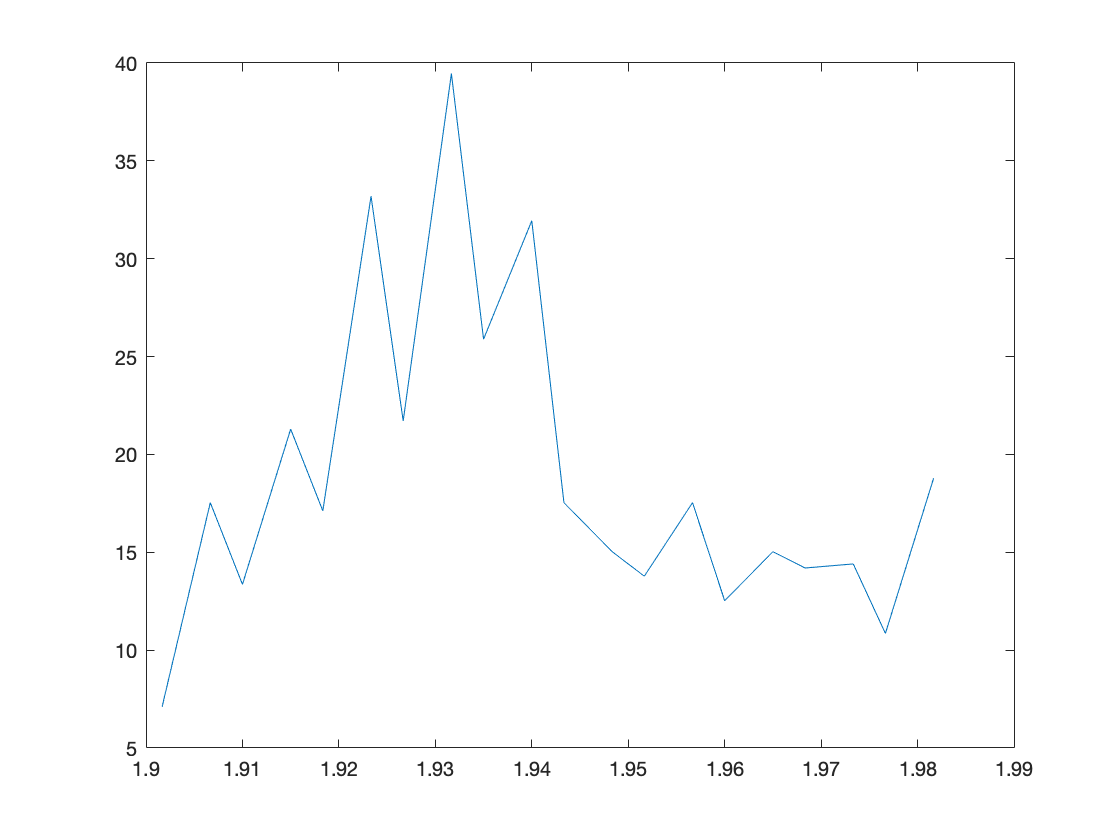

% Your code here:
plot(t(1:20),x_vel)

d) (4 points) Use the results from (a) and (b) to approximate the magnitude of the overall velocity at the first three times in the vector t given that overall velocity at time `t(i)`is 

`norm([x_vel(i) y_vel(i)])`.   Place your results in a vector named `norm_of_vel`.

% Your code here:
norm_of_vel = ones(1,3);
for i = 1:3
    norm_of_vel(i) = norm([x_vel(i) y_vel(i)]);
end
norm_of_vel

norm_of_vel =    13.6774   25.7019   16.9556


e) (10 points) You want to reduce the influence of measurement error of the x position of the stick on the quality of estimates of the horizontal stick head velocity `x_vel`. Try the following approaches and observe the effect on the apparent influence of noise. 

i. Do forward differences again, but with the stencil equal to two time steps.  Plot the results.

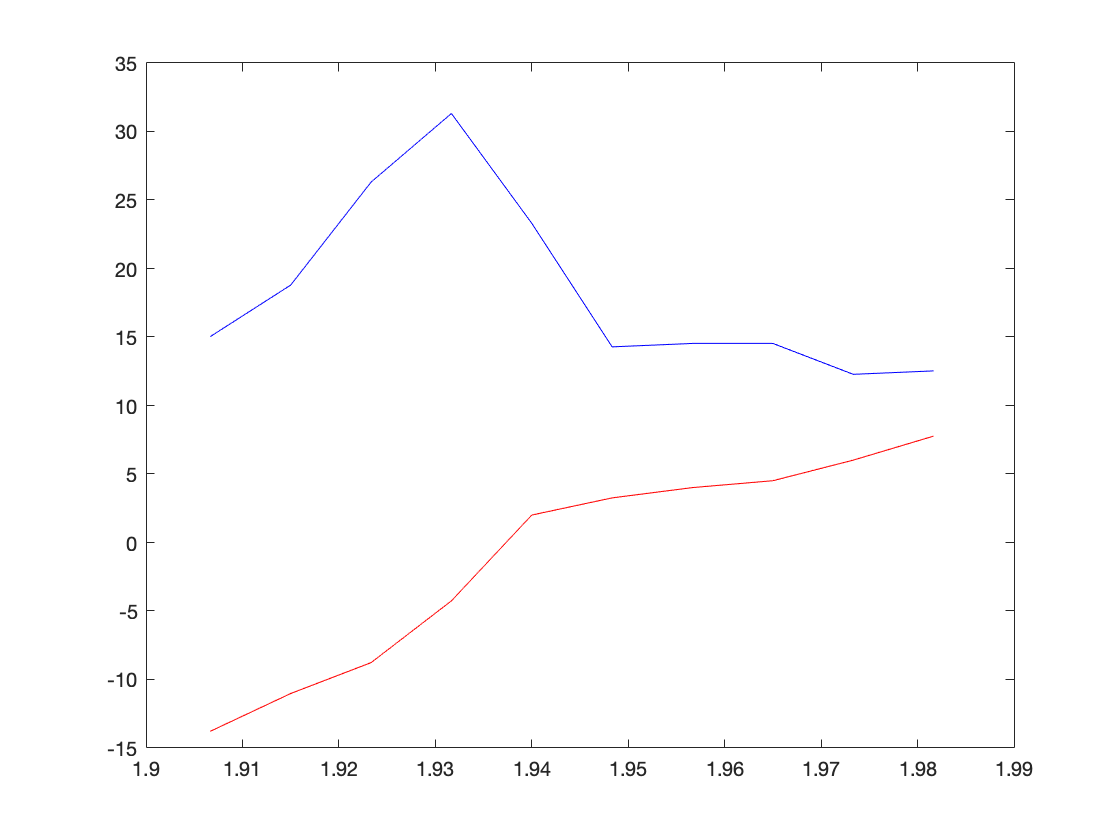

% Your code here
times = ones(1,10);
y_vel2 = ones(1,10);
x_vel2 = ones(1,10);
for i = 1:10
    times(i) = t(i*2);
    y_vel2(i) = (y_stick(2*i+2)-y_stick(2*i))/(t(2*i+2)-t(2*i));
    x_vel2(i) = (x_stick(2*i+2)-x_stick(2*i))/(t(2*i+2)-t(2*i));
end
plot(times,y_vel2,'r')
hold on
plot(times,x_vel2,'b')
hold off

ii. Fit the data to a smooth function and apply the ﬁnite diﬀerence scheme to the “smoothed” data. plot the results and compare them to those in part (b).  Because we have not covered model fitting yet, this problem needs to pull some techniques forward into the course as use them like a "black box" just for now.  Below is some code using a MATLAB built-in funtion to make a smooth function that goes through the data:

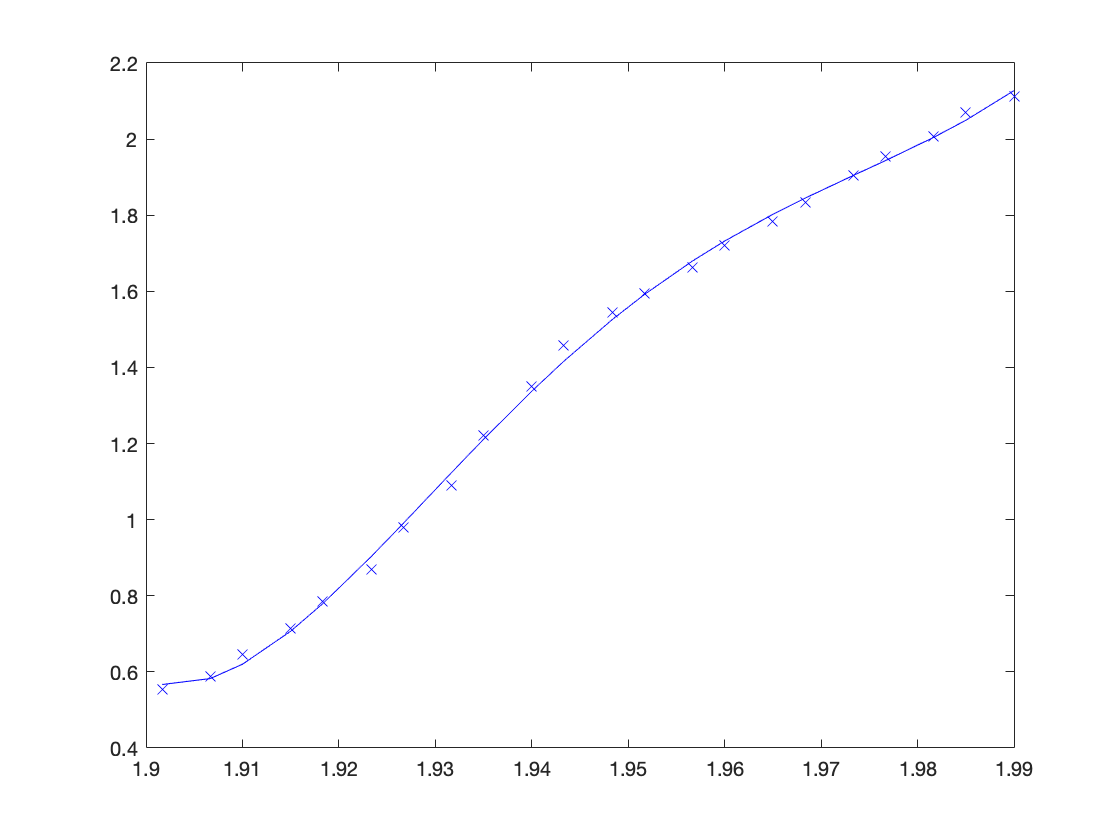

p_x= polyfit(t,x_stick,5);
x_smooth=polyval(p_x,t);
plot(t,x_smooth,'b-',t,x_stick,'bx')

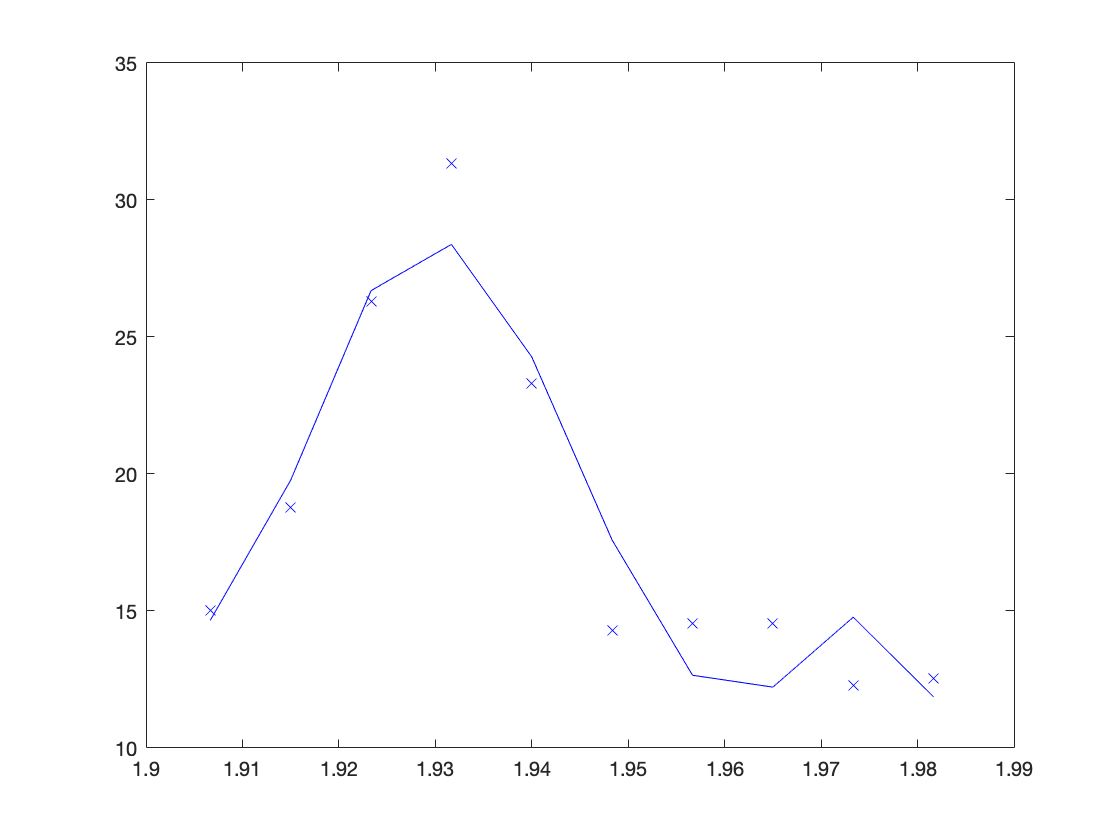

poly_x = polyfit(times,x_vel2,5);
xvel2_smooth = polyval(poly_x,times);
plot(times,xvel2_smooth,'b-',times,x_vel2,'bx')

iii. Compare the results from part (e.i) and part(e.ii) to those in part (b/c) by plotting them.

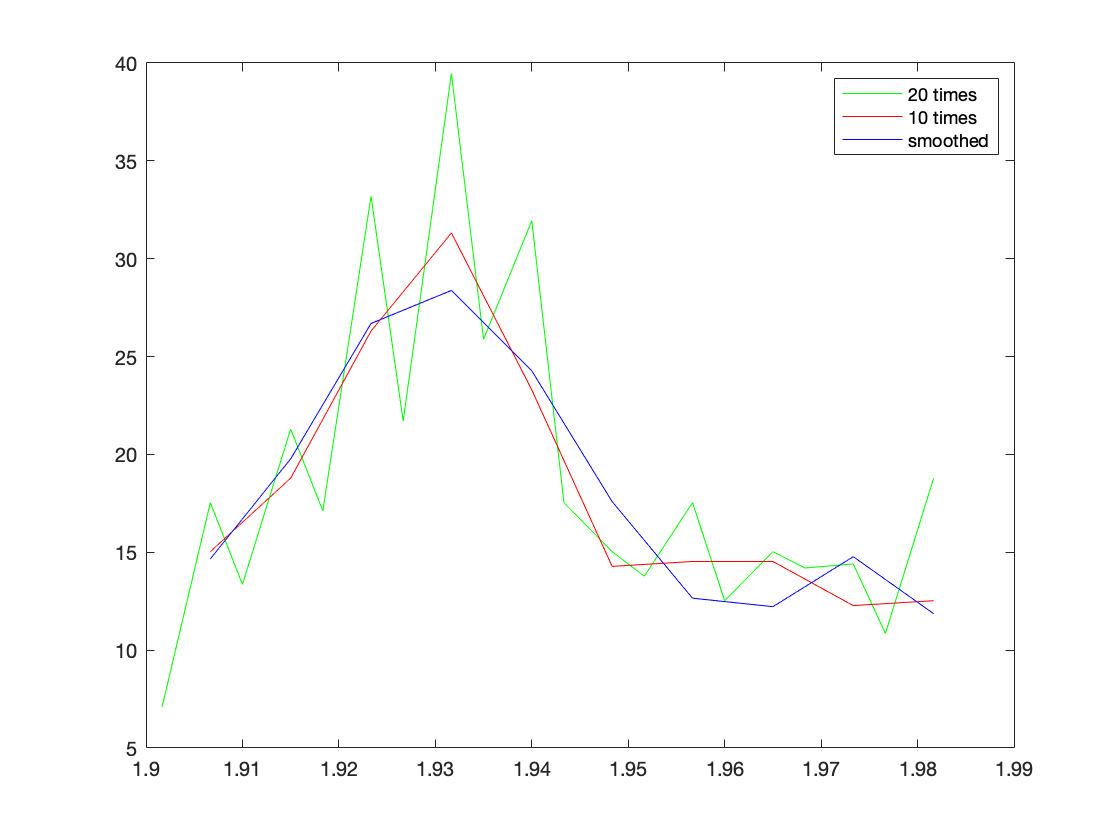

%write your code here
plot(t(1:20),x_vel,'g')
hold on
plot(times,x_vel2,'r')
plot(times,xvel2_smooth,'b-')
legend('20 times', '10 times', 'smoothed')
hold off

Comment here: The curve becomes less spikey as h becomes larger and the polynomial is "smoothed".

## Problem 3 (30 points)

Let’s say there are a set of blocks of different widths but otherwise all of uniform height, depth, and density.  The center of gravity (centroid) of each block is located equally distant from its left and right edge and its weight is proportional to its width.  We want to analyze stacks of these blocks to predict which ones will remain standing and which ones will fall over.  

 The code below makes a visualization of a stable stack of blocks (W and P vectors contain the width and position values respectively): 

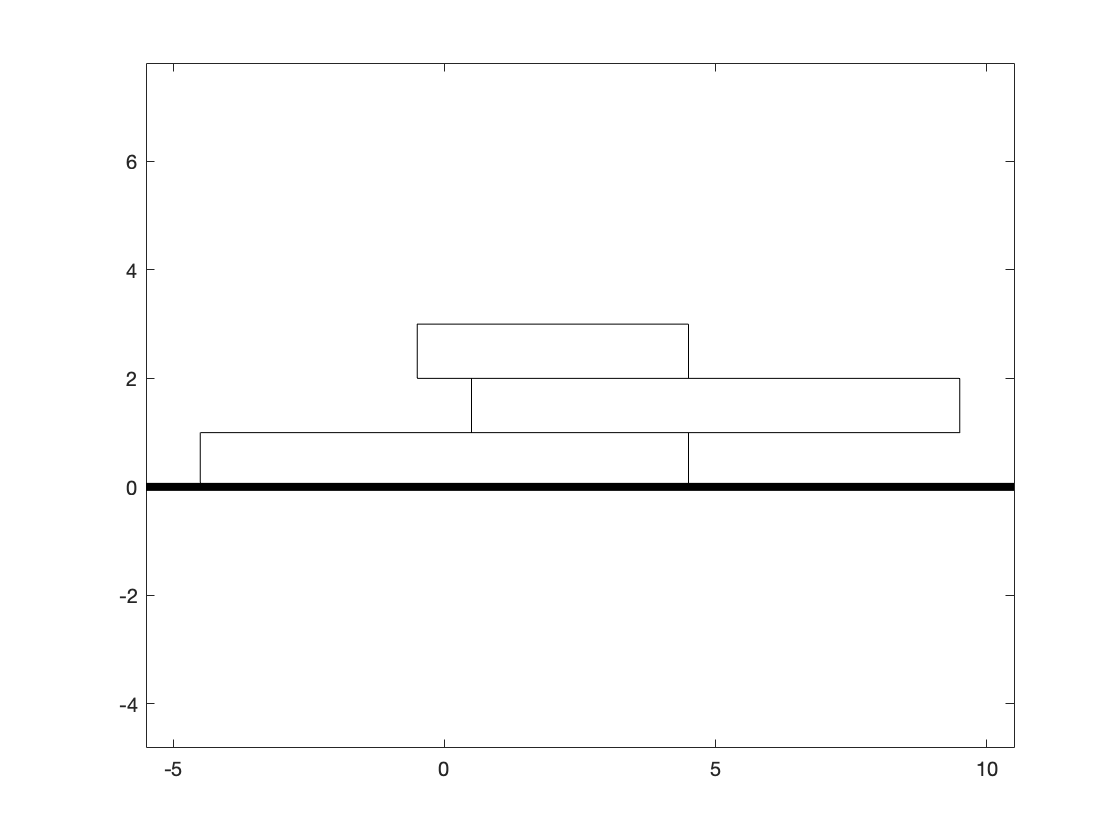

close all
W=[9 9 5];
P=[0 5 2];
plot_stack(W,P)

Even though the middle bock is sticking out a long distance, the block on top of it is placed far enough to the left that the top two blocks together have a center of gravity between the two edges of the bottom block.

The code below makes a visualization of an unstable stack of blocks:

close all
W=[9 9 5];
P=[0 4 6];
plot_stack(W,P)

Even though the middle bock is not sticking out too far (its c.g. is over the bottom block), the block on top of it is placed far enough to the right that the top two blocks together have a center of gravity beyond the right edge of the bottom block.

 (a) (15 points) Write a MATLAB function called `Stable` that takes arguments `W` and `P` that are row vectors representing widths of the blocks and centroid positions respectively (from the bottom of the stack up) and returns a single logical value that is “true” if the stack will not fall over and “false” if the stack will fall over. Please note that your functions will need to be bekwo the next break. However, you should write a test of your function here.  

% Your function will need to be below the next section break
% You should write a test of your function here
W=[9 9 5];
P=[0 5 2];
Stable(W,P)

ans = 1

W=[9 9 5];
P=[0 4 6];
Stable(W,P)

ans = 0

Stable([2 2], [3 3])

ans = 1

W_2 = [5 3 6];
P_2 = [0 -2 -2.5];
close all;
plot_stack(W_2,P_2)
Stable(W_2,P_2)

ans = 1

b) (15 points) Write a MATLAB function called Buildable that takes arguments W and P that are defined the same way as in part (a) and returns a single logical value that is “true” if the stack can be built by adding a block one at a time from the bottom up.  Each intermediate stack that exists during construction would have to be stable. Please note that your functions will need to be bekwo the next break. However, you should write a test of your function here.

% Your function will need to be below the next section break
% You should write a test of your function here
% Any unstable block is unbuildable
W=[9 9 5];
P=[0 5 2];
Buildable(W,P)

ans = 0

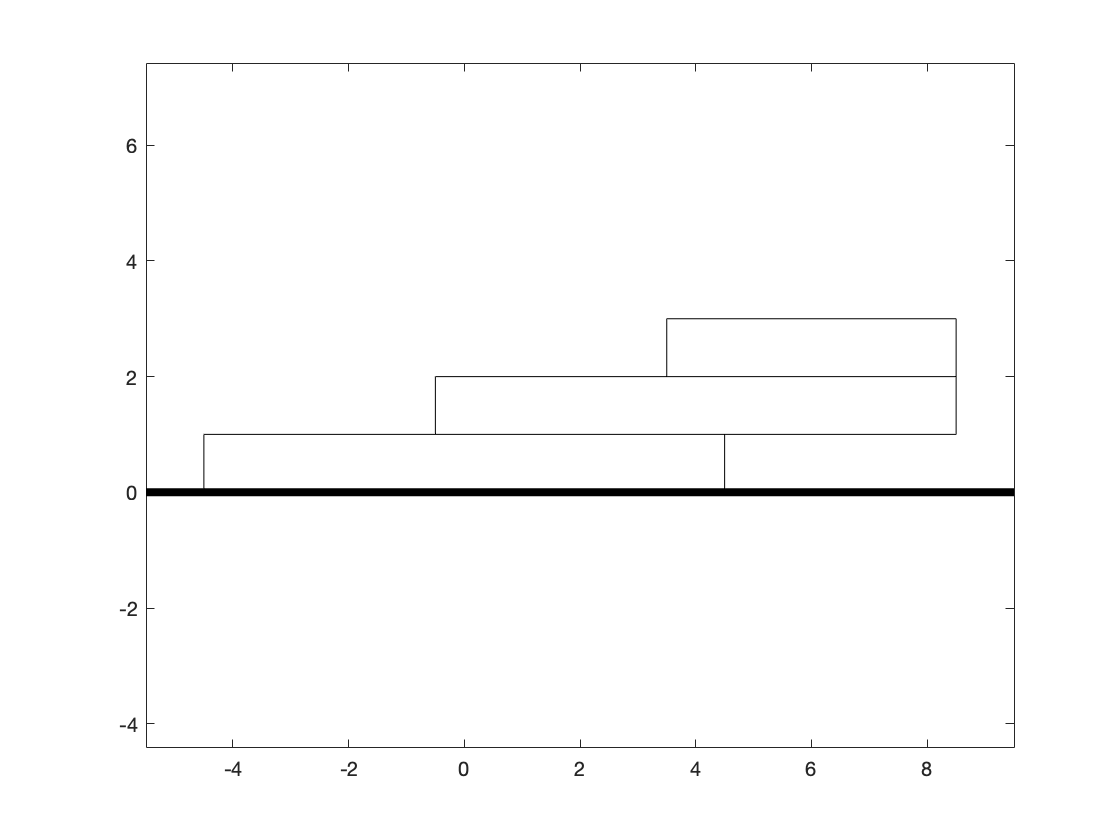

close all;
W=[9 9 5];
P=[0 4 6];
plot_stack(W,P)

Buildable(W,P)

ans = 0

Buildable([2 2], [3 3])

ans = 1

Buildable(W_2,P_2)

ans = 1

function [ S ] = Stable( W,P )
    new_W = 0;
    new_P = 0;
    for i = fliplr(2:length(W))
        new_P = ((new_W*new_P)+(W(i)*P(i)))/((new_W+W(i)));
        new_W = new_W+W(i);
    end
    if new_P<=(W(1)/2)+P(1) && new_P>=P(1)-(W(1)/2)
        S = 1;
    else
        S = 0;
    end
end

function [ B ] = Buildable( W,P )
    last_W = W(1);
    last_P = P(1);
    for i = 2:length(W)
        if P(i)<=(last_W/2)+last_P && P(i)>=last_P-(last_W/2)
            last_P = ((last_W*last_P)+(W(i)*P(i)))/(last_W+W(i));
            last_W = last_W+W(i);
            continue;
        else
            B = 0;
            return;
        end
    end
    B = Stable(W,P);
end

function []=plot_stack(W,P) % This function was given to you so you can visualize test cases for prob 3
for i=1:length(W) % For all the blocks in the stack
    plot([P(i)-W(i)/2 P(i)+W(i)/2 P(i)+W(i)/2 P(i)-W(i)/2 P(i)-W(i)/2],...
         [i-1 i-1 i i i-1],'Color',[0 0 0]) % Draw a rectangle 1 unit tall and W(i) wide
    hold on
end
axis equal
xlim([min(P-W/2-1) max(P+W/2+1)])
plot([min(P-W/2-1) max(P+W/2+1)], [0 0], 'LineWidth',4,'Color',[0 0 0]) % Draw the floor
end

function [goose] = load_goose()
% loads geometry into the workspace for problem 1

goose=[0.271 -5.602;
    -1.029 -5.302;
    -1.229 -2.502;
    -1.429 -2.302;
    -2.129 -2.702;
    -2.529 -2.402;
    -2.529 -2.002;
    -3.329 -2.002;
    -4.029 -1.802;
    -6.329 -2.302;
    -6.729 -2.102;
    -6.629 -1.802;
    -5.629 -1.002;
    -5.429 -1.002;
    -4.929 -0.602;
    -3.229 -0.102;
    -2.029 0.898;
    -1.129 1.798;
    -0.029 2.098;
    0.671 2.098;
    0.871 2.198;
    0.671 3.298;
    0.771 4.198;
    1.571 4.898;
    1.903 4.990;
    2.271 4.898;
    3.671 3.598;
    3.671 3.398;
    3.471 3.298;
    2.371 3.698;
    2.171 3.598;
    1.971 3.598;
    1.871 3.698;
    1.571 3.598;
    1.571 3.098;
    1.671 2.998;
    2.171 2.598;
    3.171 2.298;
    3.871 1.898;
    4.371 1.398;
    4.371 0.898;
    4.171 0.198;
    3.271 -0.702;
    1.471 -2.002;
    0.171 -2.702;
    -0.729 -3.502;
    -0.729 -5.102;
    0.473 -5.202;
    0.271 -5.602];
end % load_goose